# Unsupervised Learning 

[⇦ Main Menu](matlab:open('../MainMenu.mlx'))

In this script, we will apply unsupervised learning techniques to a large dataset of blood serum samples to explore potential patterns associated with ovarian cancer.

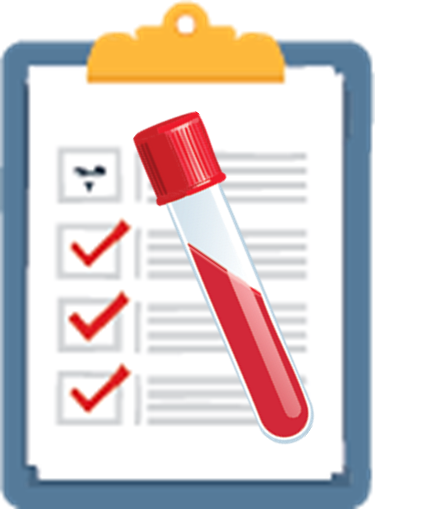

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**. Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The   and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Unsupervised Discovery: Finding Hidden Patterns in Blood to Detect Ovarian Cancer

What if we could discover new, data-driven insights without even knowing what to look for in advance?

In this project, we apply **unsupervised learning** to a dataset of blood serum samples from patients, each containing a set of biochemical measurements. Unsupervised learning allows us to explore the data without predefined categories. We aim to explore whether natural groupings in the data correspond to the presence or absence of ovarian cancer by applying clustering and dimensionality reduction techniques.

### Prepare Data for Machine Learning

To begin, we load and examine the dataset by reviewing its structure, contents, and dimensions. This step helps us understand what each patient sample represents and the amount of information contained within it. By familiarizing ourselves with the data early on, we set the stage for applying unsupervised learning techniques that can help us distinguish between patients with and without ovarian cancer.

  **Try.** Load and format the data for machine learning. Learn more about the `LoadOvarian` function [here](matlab: doc LoadOvarian).

 
Preview = false;
Help = false;
[OvarianInputs,OvarianTargets] = LoadOvarian(Preview,Help); % Live function to import data and format data into tables

 **Exercise 1. **How many patients are included in this dataset?

CheckAnswer("Exercise1","");
 

## Dimensional Reduction with Principal Component Analysis

When analyzing our dataset, we face a major challenge: each of the 216 patients is described by 100 predictor variables. This high-dimensional data makes it nearly impossible to visualize patterns or group differences using traditional plots, which are limited to two or three dimensions. Simply plotting the first two variables would ignore the remaining 98, potentially missing critical information.

To address this, we use **Principal Component Analysis (PCA)** which is a dimensionality reduction technique. PCA transforms your original variables into a new set of axes which are called *principal components *that better capture the structure of the data. 

Let’s consider a simple 2D example. In the plot, the diagonal line represents the **first principal component (PC1)**, which is the direction of maximum variance in the data. The **second principal component (PC2)** is orthogonal to **PC1** and captures the next highest variance not already explained by **PC1**.

PCA works by projecting the data onto these principal components and discarding the original coordinate system which means we retain only the coordinates along the selected principal components, effectively reducing the dimensionality of the data while preserving as much of its variability as possible.

** Demonstration**. Visualize dimensional reduction with a 2D dataset.

 
x = 0:5;
y = [x-rand(size(x)); x+rand(size(x))];
fig = FullScrnFig();
tiledlayout(1,2)

nexttile(1) % Plot dataset on original axes
scatter(x,y)
hold on
yline(0,SeriesIndex=3)
xline(0,SeriesIndex=4)
hold off
formatPlot()
legend(["Dataset 1","Dataset 2","x-axis","y-axis"],Location="bestoutside")
xlabel("Original x-axis")
ylabel("Original y-axis")
title("Dataset on Original Axis")

nexttile(2) % Plot dataset on transformed axes
scatter(x,y)
hold on
coeffs = pca(y');
xVals = -5:5;
plot(xVals,coeffs(2,1)/coeffs(1,1)*xVals)
plot(xVals,coeffs(2,2)/coeffs(1,2)*xVals)
hold off
formatPlot()
legend(["Dataset 1","Dataset 2","PC1","PC2"],Location="bestoutside")
xlabel("New x-axis")
ylabel("New y-axis")
title("Dataset on Transformed Axis")

### Reduce the Dimensions of the Dataset 

To better understand our dataset and simplify the analysis, we'll apply **Principal Component Analysis (PCA)** which helps reduce the number of dimensions in our data while preserving as much of the original variance as possible. Our PCA analysis will make it easier to identify complex patterns and highlight the most informative features by revealing clusters in our data. We will have three important output variables to help us make sense of our dataset:

- **Coeffs**: The principal component coefficients that define the direction of maximum variance. They define how the original features combine to form each component.

- **TransformedData**: The representation of the original data in the new PCA space, also known as the transformed data. This transformed representation reduces dimensionality while preserving as much variance as possible.

- **Explained**: The amount of variance explained by each principal component. The **second principal component (PC2)** is orthogonal to the first (**PC1**) and captures the next highest amount of variance in the data that is not already explained by **PC1**.

  **Try. **Perform PCA on the dataset.

% Principal Component Analysis
 
[Coeffs,TransformedData,~,~,Explained] = pca(OvarianInputs{:,2:end}); % Perform PCA on dataset
disp("PCA performed on dataset.")

 **Exercise 2. **Based on the definitions above, which output variable should you enter to describe the amount of variance by each principal component?

CheckAnswer("Exercise2","");
 

## Perform PCA Analysis of the Dataset

### Visualize the Number of Components to Keep

The **explained variance** describes how much of the original data's information is captured in each principal component, expressed as a percentage of the total variance. Principal components are ranked by how much variance they capture from the original dataset. If the first few components account for 95% of the total variance, we can safely disregard the remaining components without losing significant information.

We can use a **Scree plot **which is a plot of the explained variance vs. the principal component number to visualize the number of principal components to keep. A scree plot physically looks like a line graph overlaying a bar graph with a very distinct shape which is often described as looking like a descending staircase. Each bar represents a principal component and the line shows the cumulative percentage of PCA contributors to the variance. The plot typically shows a steep drop followed by a gradual flattening. Look for the "elbow" in the bar graph, where the steep decline begins to level off. This point indicates that adding more components offers little improvement in explaining the data. Components before the elbow capture meaningful patterns, while those after it mostly reflect noise or minor details.

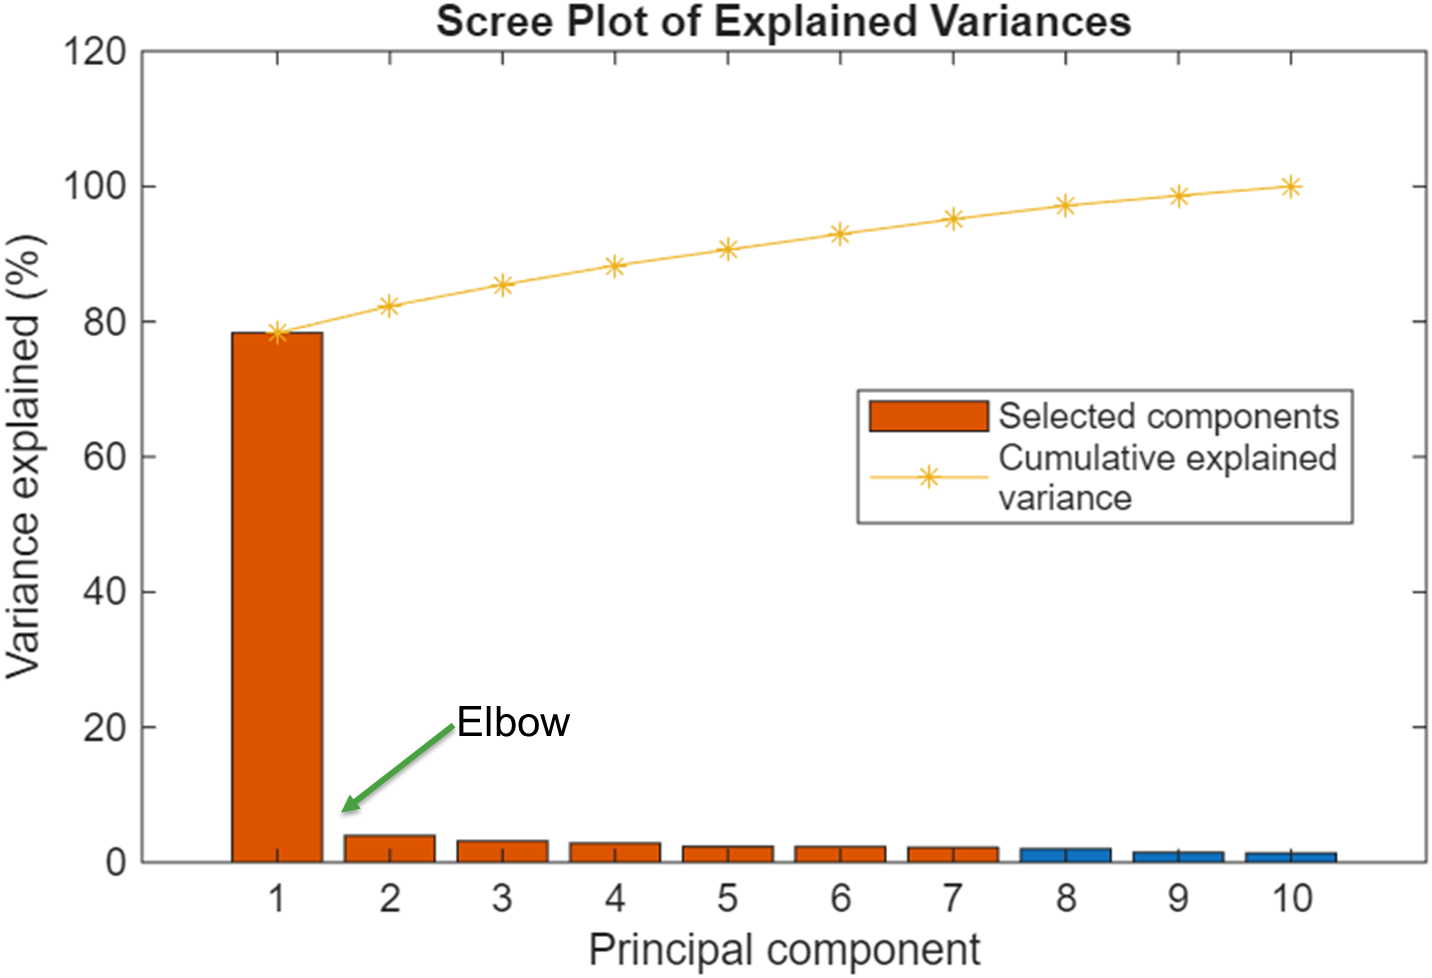

  **Try. **Find the number of components to keep from the Scree Plot.

- *Vary the number of components to keep by selecting values from the dropdown menu until you attain *$>95\text{%$*.*


CheckVariable("Explained") % Check to make sure variables are loaded - generates an error message if not.

numberOfComponentsToKeep = "Select";
if ~strcmp(numberOfComponentsToKeep,"Select") % Only perform the analysis if the number of components to keep is chosen
    % Format display results
    FullScrnFig(); %#ok<UNRCH>
    formatPlot()
    % Check to make sure variables are loaded - generates an error message if not.
    colorMap = colormap("lines");
    barPlot = bar(Explained);
    hold on
    plot(cumsum(Explained),"*-","Color",colorMap(3,:));
    hold off
    barPlot(1).FaceColor = "flat";
    barPlot(1).CData(1:numberOfComponentsToKeep,:) = repmat(colorMap(2,:),[numberOfComponentsToKeep 1]);
    label = ["Selected components"; sprintf("Cumulative explained\nVariance")];
    legend(label,Location="bestoutside");
    title("Scree Plot of Explained Variances")
    xlim([0 20])
    xlabel("Principal component")
    ylabel("Variance explained (%)")
    cumsumExplained = round(sum(Explained(1:numberOfComponentsToKeep)));
    disp("The number of components to keep accounts for " + cumsumExplained + "% of variance explained.")
else
    warning("Select a valid option.")
    return
end

### Compute the Number of Components to Explain >95% of the Variance

Rather than the trial and error approach from above, we can also compute the number of components from the explained variance required to explain at least 95% of the variance by taking the cumulative sum of the explained values over the sum of the explained values. 

  **Try. **Compute the number of components.

 
CheckVariable("Explained") % Check to make sure variables are loaded - generates an error message if not.
% Compute number of components from explained variance
enoughExplained = cumsum(Explained)/sum(Explained) >= 95/100;
numberOfComponentsToKeep = find(enoughExplained,1);
disp("The number of components needed to explain at least 95% of the variance is " + num2str(numberOfComponentsToKeep) + ".")

### Perform K-Means Clustering on the PCA-Reduced Data

Let's apply unsupervised learning to uncover natural groupings in our patient dataset using **k-means clustering**, a method that assigns each observation to one of $k$ groups based on similarity.

The first step is choosing the number of clusters, $k$. While there are mathematical techniques to estimate the optimal value, it's common to experiment with different values or use domain knowledge. In our case, we expect two main groups: patients with cancer and those without, so we'll start with $k=2$.

Although the underlying math is beyond our scope, k-means clustering finds the best way to divide the data into $k$ groups based on the distance between points. Here, we'll cluster the data using the first two principal components for visualization:

  **Try.** Perform k-means clustering on PCA-reduced data.

- *Choose an appropriate value of *$k$* to use to cluster your PCA-reduced data.*

- *Click the 'Plot K-means Clusters for Data' button.*

k = 2; % Number of k-clusters
 

CheckVariable("TransformedData") % Check to make sure variables are loaded - generates an error message if they are not
fig = FullScrnFig(); % Set the graph to display fullscreen

if ~strcmp(k,"Select") % Only perform the analysis with a selection of a k value
    color = lines(k);
    [idx,~] = kmeans(TransformedData(:,1:2),k); % Use first 2 PCs to perform k-means clustering on PCA-reduced dataset

    % Plot k-means clusters with colors indicating the cluster number
    gscatter(TransformedData(:,1),TransformedData(:,2),idx,color,"od","filled");
    ax = gca;
    ax.Box = "on";
    xlabel("Principal Component 1");
    ylabel("Principal Component 2");

    % Create dynamic legend based on the number of clusters
    legendStrings = arrayfun(@(x)sprintf("Cluster %d",x),1:k,UniformOutput=false);
    legend(legendStrings,Location="bestoutside");
else
    warning("Select a valid option.")
end

### Quantitative Cluster Comparison with a Confusion Matrix

To evaluate the performance of our clustering, we can use a **confusion matrix** to compare the predicted cluster labels with the known diagnostic labels. In this matrix, the rows represent the true classes and columns represent the predicted classes. Each cell in the matrix shows the number of instances that fall into a specific combination of true and predicted classes. The diagonal elements indicate correct classifications or true positives and negatives for each class, while the off-diagonal elements represent misclassifications, the false positives and negatives. We can also normalize the matrix to express the number of correctly and incorrectly classified observations as percentages of the total observations within each true class.

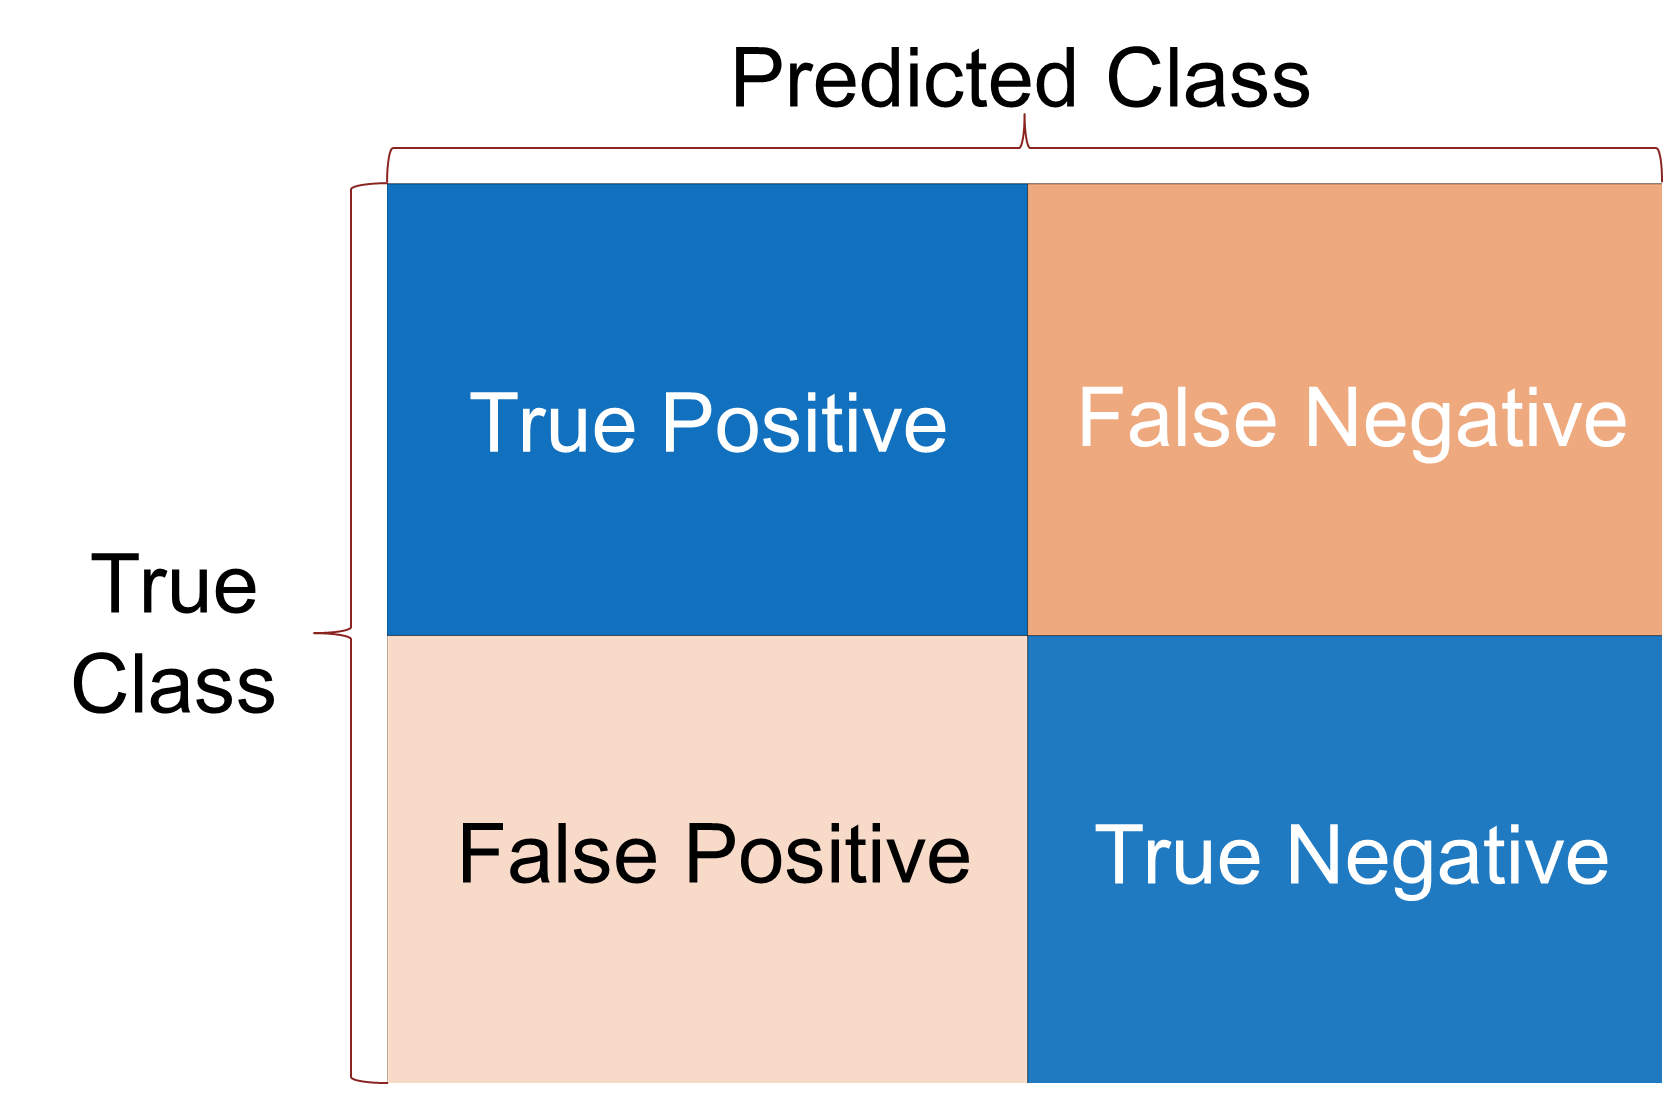

### Compare Clusters to Cancer Diagnoses

After applying **k-means clustering** to our PCA-reduced dataset, we will assess how well the resulting clusters align with the known cancer diagnoses. To do this, we use a **confusion matrix** to compare the predicted cluster assignments with the actual diagnostic labels. In this context, the rows of the **confusion matrix** represent the true cancer status of each patient, and the columns represent the assigned cluster labels from the PCA-reduced dataset. We convert the first column of the `OvarianTargets` dataset into a categorical array named `diagnosis`, where a value of 1 indicates the presence of cancer and 0 indicates no cancer. The second column is the inverse of the first and is therefore redundant for our analysis. By constructing the confusion matrix, we can quantify how accurately the clustering reflects the underlying diagnostic categories.

After applying to our **PCA-reduced dataset**, we aim to assess how well the resulting clusters align with the known cancer diagnoses. Specifically, we will compare the cluster assignments to the cancer status of each patient, as indicated in the `OvarianTargets` dataset. We will convert the first column of `OvarianTargets` into a categorical array named `diagnosis`, since it encodes cancer presence of 1 for cancer, and 0 for no cancer. The second column is its inverse and thus redundant for our analysis.

  **Try**. Display **confusion matrix** to compare clusters to cancer diagnoses. Vary the number of components to keep to determine the impact of performing PCA on the dataset. Is there a change in the confusion matrix with performing k-means clustering on the PCA-reduced dataset vs. the complete dataset?

mode = "PCA-reduced dataset";
 
switch mode
    case "PCA-reduced dataset"
        [Coeffs,TransformedData,~,~,Explained] = pca(OvarianInputs{:,2:end}); % Perform PCA on dataset
        [idx,C] = kmeans(TransformedData(:,1:3),2);
    case "Full dataset"
        [idx,C] = kmeans(OvarianInputs{:,2:end},2);
    otherwise
        disp("Select a mode.")
        return
end

% Convert the first row of OvarianTargets to a categorical variable
diagnosis = categorical(OvarianTargets{:,1}); % Transpose to match length of idx

% Convert cluster indices to categorical
% clusters = categorical(idx);
clusters = categorical(idx(:) - 1);

% Create a confusion matrix using confusionchart
figure
cm = confusionchart(clusters,diagnosis);
cm.Title = "Confusion Chart";
cm.XLabel = "Predicted Class";
cm.YLabel = "True Class";
if ~isMATLABReleaseOlderThan("R2025a")
cm.RowDisplayLabels = ["Cancer", "Normal"];
cm.ColumnDisplayLabels = ["True","False"];
else
end

The accuracy of our predictions can be determined by the following equation:


$$\text{Accuracy} = \frac{\text{True Positives +True Negatives}}{\text{True Positives + False Positives + True Negatives + False Negatives$$


PerCentTruePosNNeg = ((93+83)/(93+83+38+2))*100;
disp("The accuracy of our clustering is " + num2str(round(PerCentTruePosNNeg)) + "%.");

 **Reflect**. How well do you think the k-means clustering matches up with the patient diagnosis?

In this case, one cluster predominantly captured patients with ovarian cancer, while the other mostly included those without, showing a meaningful alignment with clinical diagnoses. The "cancer-like" cluster contained most of the true positives and a few false positives, while the "non-cancer-like" cluster included most of the true negatives along with the false negatives. This indicates that the model was highly accurate in identifying non-cancer cases but missed several actual cancer cases with resulted in an overall accuracy of approximately 81%, indicating that the model was generally effective, though it missed several actual cancer cases.

Although exact percentages are not shown in the confusion matrix, the raw counts suggest a low false positive rate, with only a few healthy individuals misclassified. However, the higher false negative rate is more concerning in a clinical context, as it risks missing patients who need treatment.

Still, the use of **k-means clustering** on PCA-reduced dataset revealed meaningful structure in the dataset with minimal supervision. This kind of unsupervised pattern recognition holds promise for exploratory analysis and could support early detection efforts when combined with more sensitive diagnostic tools.

## Glossary

**Confusion matrix:**A matrix that shows how predicted labels compare to actual labels, helping to evaluate model accuracy at a glance. (↑ Return to Text)

**K-means clustering: **A method that groups data into clusters based on similarity, helping to show natural patterns. (↑ Return to Text)

**Principal Component Analysis (PCA): **A technique that reduces complex data into fewer dimensions by finding the directions of greatest variance, making patterns easier to visualize and interpret. (↑ Return to Text)

**Scree plot: **A plot that shows how much variance each principal component explains, with the "elbow" indicating the optimal number to keep. (↑ Return to Text)

**Unsupervised Learning: **A type of machine learning that analyzes unlabeled data to discover hidden patterns or groupings without predefined categories. (↑ Return to Text)

## Further Exploration

You can explore further into clustering algorithms for machine learning in [Machine Learning Methods: Clustering](https://www.mathworks.com/matlabcentral/fileexchange/135381-machine-learning-methods-clustering).

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function CheckAnswer(exerciseID, option)
% Function to check answers for exercises
% Define the structure for each exercise (answers and hints)
exercises = struct( ...
    "Exercise1",struct("answer","216","hint","How many patients does the MATLAB documentation describe?"),...
    "Exercise2",struct("answer","Explained","hint","Which output specifically quantifies how much of the original data's variability is captured by each principal component?")...
    );
% Check if the exercise exists
if isfield(exercises,exerciseID)
    CorrectAnswer = exercises.(exerciseID).answer;
    hint = exercises.(exerciseID).hint;

    % Compare answers
    if isequal(option,CorrectAnswer)
        disp("You are correct.")
    elseif isequal(option,"Select")
        warning("Select a valid option.")
    else
        warning("%s",hint)
    end
else
    warning("Exercise not found.")
end
end

function formatPlot()
% Function to format axes
ax = gca;
ax.Box = "on";
ax.XLim = [-2 5];
ax.YLim = [-2 5];
ax.XGrid = "on";
ax.YGrid = "on";
ax.XMinorGrid = "off";
ax.YMinorGrid = "off";
ax.XTick = [0 5];
ax.YTick = [0 5];
axis(ax,"square");
end

function fig = FullScrnFig()
% Function to make images and graphs display fullscreen.
fig = figure;
set(fig,"Units","pixels")
screensize = get(0,"ScreenSize");
set(gcf,"Position",screensize);
end

function CheckVariable(errorID)
% Function to verify variables are in the workspace
checks = struct( ...
    "TransformedData", struct("msg","PCA coefficients are not found. Please perform PCA on dataset."), ...
    "Explained", struct("msg","Explained variance is not found. Please perform PCA on dataset."), ...
    "numberOfComponentsToKeep",struct("msg", "numberOfComponentsToKeep is not found. Compute the number of components to keep.") ...
    );
if isfield(checks, errorID)
    % Check if the variable exists in the base workspace
    if ~evalin('base',sprintf('exist("%s", "var")',errorID))
        error("%s",checks.(errorID).msg); % Stop function from running and display error message
    end
end
end